# ADCS Problem Set 7

Dillon Allen

## Develop a simulation to show thruster control with a phase-plane controller

Initial Variables

Iy = 1000 % kg-m^2

Iy = 1000

Tc = 1    % N-m

Tc = 1

We are given the initial conditions

theta_0 = -2   % degrees

theta_0 = -2

theta_dot_0 = -0.2 % degrees / sec

theta_dot_0 = -0.2000

t_sim = 200    % seconds

t_sim = 200

Every 1 second, thrusters fire torque for 1 second pulse, with constant thrust

### Relevant Equations

#### Positive Torque

#### 
$$\dot{\theta}(t) = \dot{\theta}(0) + \frac{T}{I_y} t$$


#### 
$$\theta(t) = \theta(0) + \dot{\theta}(0) t + \frac{T}{2 I_y} t^2$$


#### Torque turned off

#### 
$$\dot{\theta}(t) = \dot{\theta}(0)$$


#### 
$$\theta(t) = \theta(0) + \dot{\theta}(0) t$$


#### Negative Torque

#### 
$$\dot{\theta}(t) = \dot{\theta}(0) - \frac{T}{I_y}t$$


#### 
$$\theta(t) = \theta(0) + \dot{\theta}(0) t - \frac{T}{2 I_y} t^2$$


#### Hints:

1. Write down the equations for the two drift lanes

2. Write the logic for the thruster control

3. Use equations from the notes to avoid integration 

#### Code

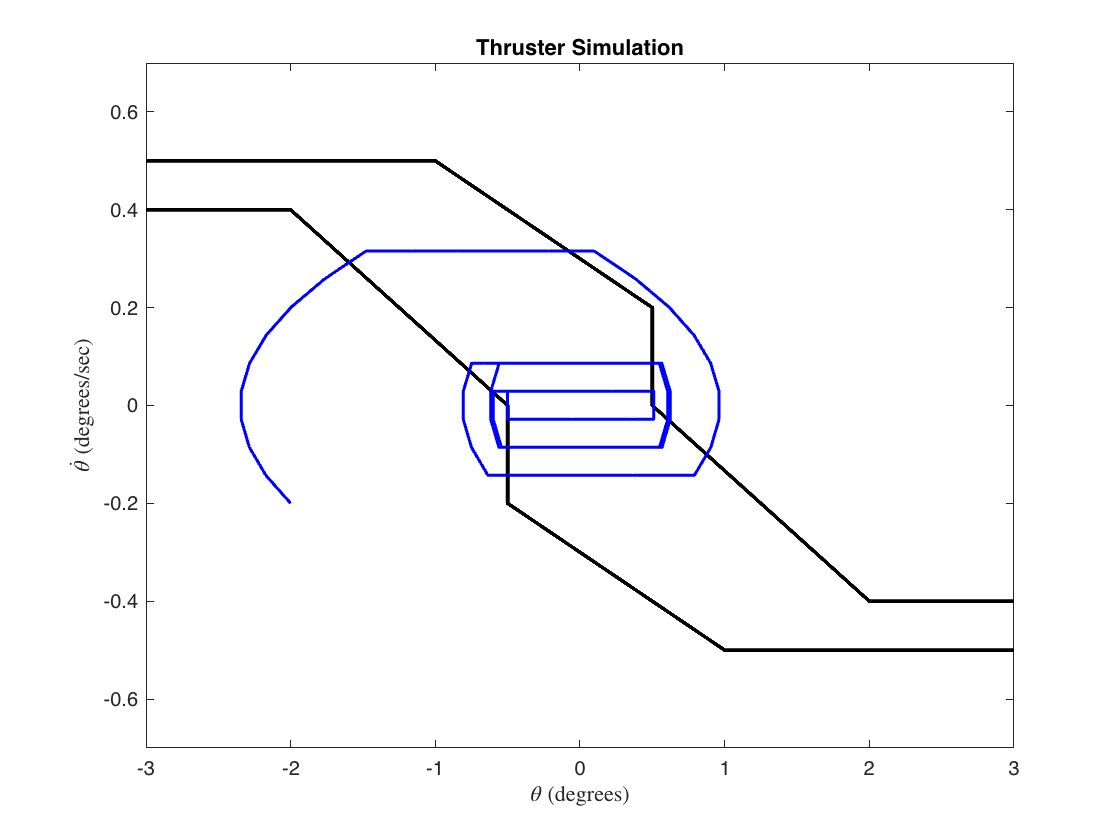

% The drift lanes can be turned into functions
% as seen below. We can use a for loop to run
% through the simulation time and have a 
% function that checks boundaries for us.
% Then, we will plot theta vs omega

% general structure of program
% for t = 1 : t_sim
%   check theta, theta_dot
%   if under leftDrift
%       apply positive torque eqs
%       store theta,omega
%   elif inbetween
%       torques off eqs
%       store theta,omega
%   else
%       apply negative torques
%       store theta,omega
%
% after loop
% plot drift lines
% plot theta vs theta_dot
theta_History     = []; % degrees
theta_dot_History = []; %degrees
theta_History(1) = theta_0;
theta_dot_History(1) = theta_dot_0;

for t = 1 : t_sim
    % Calculate drift lane values
    thetaOld = theta_History(t);
    theta_dotOld = theta_dot_History(t);
    theta_dot_l = leftDrift(thetaOld);
    theta_dot_r = rightDrift(thetaOld);

    if (theta_dotOld < theta_dot_l)
        % fire positive torque
        [theta1, theta_dot1] = ...
            positiveTorque(thetaOld, theta_dotOld);
    elseif (thetaOld <= -0.5 && ...
            (theta_dot_History(t) >= -0.2 && ...
            theta_dot_History(t) <= 0))
        % fire positive torque
        [theta1, theta_dot1] =  ...
            positiveTorque(theta_History(t),...
            theta_dot_History(t));

    elseif (theta_History(t) >= 0.5 && ...
            (theta_dotOld >= 0 && ...
            theta_dotOld <= 0.2))
        % fire negative torque
        [theta1,theta_dot1] = ...
            negativeTorque(thetaOld,...
            theta_dotOld);

    elseif (theta_dotOld > theta_dot_l && ...
            theta_dotOld < theta_dot_r)
        % no torque
        [theta1, theta_dot1] = ...
            noTorque(thetaOld, theta_dotOld);

    elseif (theta_dotOld > theta_dot_r)
        % negative torque
        [theta1, theta_dot1] = ...
            negativeTorque(thetaOld, theta_dotOld);

    else
        fprintf("Error in theta or theta drift")
    end

    theta_History(t+1) = theta1;
    theta_dot_History(t+1) = theta_dot1;

end


% Visualize the results
thetaPlot = linspace(-3,3,10000);
for x = 1:length(thetaPlot)
    LeftLanePlot(x) = leftDrift(thetaPlot(x));
    RightLanePlot(x) = rightDrift(thetaPlot(x));
end

plot(thetaPlot, RightLanePlot, 'Color','black', 'LineWidth',2);
hold on
plot(thetaPlot, LeftLanePlot, 'Color', 'black', 'LineWidth',2);
plot(theta_History, theta_dot_History, 'Color','blue','LineWidth',1.5)
xlabel("$\theta$ (degrees)", 'Interpreter','latex')
ylabel("$\dot{\theta}$ (degrees/sec)", 'Interpreter','latex')
title("Thruster Simulation")
axis([-3 3 -0.7 0.7])

function theta_dot_l = leftDrift(theta)
% This function follows the left drift lane
% presented in the homework
% Since this is a piecewise function, this will
% be broken into for loops
% does not account for the vertical line
    if theta >= -3 && theta <= -2
        theta_dot_l = 0.4 ;
    elseif theta > -2 && theta <= -0.5
        slope1 = (0 - 0.4)/(-.5 - (-2));
        theta_dot_l = slope1 * (theta - (-2)) + 0.4;
    elseif theta > -0.5 && theta <= 1
        slope2 = (-0.5 - (-0.2))/(1 - (-0.5));
        theta_dot_l = slope2*(theta - (-0.5)) + (-0.2);
    elseif theta > 1 && theta <= 3
        theta_dot_l = -0.5;
    else
        fprintf("%d not in plot", theta);
    end
end

function theta_dot_r = rightDrift(theta)
    % this function is for the right drift lane
    % presented in the homework
    % this code does not account for the
    % vertical line part
    if theta >= -3 && theta <= -1
        theta_dot_r = 0.5;
    elseif theta > -1 && theta <= 0.5
        slope1 = (0.2 - 0.5)/(0.5 - (-1));
        theta_dot_r = slope1*(theta - (-1)) + 0.5;
    elseif theta > 0.5 && theta <= 2
        slope2 = (-0.4 - 0)/(2 - 0.5);
        theta_dot_r = slope2*(theta - 0.5);
    elseif theta > 2 && theta <= 3
        theta_dot_r = -0.4;
    else
        fprintf("%d not in plot", theta)
    end
end

function [theta, theta_dot] = positiveTorque(theta0, theta_dot0)
    Iy = 1000; % kg-m^2
    Tc = 1;    % N-m
    TI_deg = (Tc/Iy) * (180/pi); % turn into deg
    theta = theta0 + theta_dot0 + TI_deg/2;
    theta_dot = theta_dot0 + TI_deg;
end

function [theta, theta_dot] = noTorque(theta0, theta_dot0)
    theta_dot = theta_dot0;
    theta = theta0 + theta_dot0;
end

function [theta, theta_dot] = negativeTorque(theta0, theta_dot0)
    Iy = 1000; % kg-m^2
    Tc = 1;    % N-m
    TI_deg = (Tc/Iy) * (180/pi); % turn into deg
    theta = theta0 + theta_dot0 - TI_deg/2;
    theta_dot = theta_dot0 - TI_deg;
end